% LOADING MOUSE EXPERIMENT VARIABLES - saved out in imThreshPass

% navigate to BALL DATA folder, then to to DIFF folder to 
% save figs/vars at END

% addpath F:\Kristen\Widefield2\041021_G6H277RT_RIG2\balldata_G6H277RT 
addpath F:\Kristen\Widefield2\041121_G6H277RT_RIG2\balldata_G6H277RT

close all
clear all

% load SUBJ mat file: 

load('G6H277RT_subj.mat')
% load('EE81LT_subj.mat')

% load SESSIONS mat file:
% doBehavior generates one of these files per session:

load('20210411T123140_25.mat') % 277RT 041121
% load('20210410T195352_20.mat') % 277RT 041021

% load('20210406T144122_9.mat') % EE81LT 040621
% load('20210405T132423_8.mat') % EE81LT 040421 the real date is 4/5 but says 4/4 on file name
%load('20210402T161748_7.mat') % EE81LT 040221 
% now this one is in the EE81LT folder 
% for 4-4 and has the most trials - 656
% % load('20210402T133555_14.mat') % inside 277RT 040221
% % at first I thought misnamed EE81LT 040221's missing ball data from 
% % 4/2 was here, in the 277RT balldata folder from 4-2
% % but, while it has the correct (newest) duration settings
% % it only has but 229 trials
% load('20210305T150519_3.mat') % 277RT 030521
% load('20210311T161951_5.mat') % 277RT 031121
% OR:
% load('20210311T154010_4.mat') % 277RT 031121 - this is the last session that day so maybe the correct one? I think I deleted the previous imaging session just because eye cam didnt work?
% load('20210204T164434_3.mat') % EE1LT 020421
% load('20210204T131006_5.mat') % 277RT 020421
% load('20210107T155415_1.mat') % 277RT 010721
% load('20210107T140819_6.mat') % EE81LT 010721 (file acccidentally named 010621)

% GET TOPOX,Y, SHOW POLAR MAPS
% get topox & topoy MAPS & make polar maps

% topox
[f p] = uigetfile('*.mat','topox maps file')
load(fullfile(p,f),'mapNorm');
topox = polarMap(mapNorm{3}); % polar map = projecting features from plane to sphere

% show polar map
f1 = figure
imshow(topox)
title('topox polar map of normalized WF signal')

% topoy
[f p] = uigetfile('*.mat','topoy maps file')
load(fullfile(p,f),'mapNorm','map');
topoy = polarMap(mapNorm{3});

% polar map
f2 = figure
imshow(topoy)
title('topoy polar map of normalized WF signal')

%% get THRESH MAPS

[f p] = uigetfile('*.mat','maps file');

downsize = 0.25; % why resize by this factor?
load(fullfile(p,f));

%%  DOWNSIZE all 3 videos

df = imresize(dfof_bg,downsize);
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);


% SAVE 1st VARS - get in right FOLDER!

save('041021_277RT_imThressPass1stVars.mat','-v7.3') % saves map files just opened & other vars


% FIG TITLES

% mouse id
subjName = subjData{1,1}.name; 

% date
[filepath,name,ext] = fileparts('20210411T123140_25.mat');
datePart = name(1:8);
year = datePart(1:4);
month = datePart(5:6);
day = datePart(7:8);
date = sprintf('%s ', month, day, year);

% legend info
reigons = {'V1','LM','RL','PM','control'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16','33','66','133','266'};


% VARS 4 FIGS
% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
% in case: conOrderedByTrial = con(idxOnsetsMeetBothCriteria)
uniqueContrasts = unique(con); % for looping over contrast values later


%%  DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); 
% in case: durOrderedByTrial = dur(idxOnsetsMeetBothCriteria)
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER

% putting together dur & con so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];

% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x #trials
% conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria); 

% BROAD look at ACTIVITY over WHOLE FOV

titleText = sprintf('passivie viewing threshold movie \n no baseline subtraction');
clear t
t = suptitle(sprintf('%s: ',date,subjName,titleText));
%set(t, 'FontSize', 12);

clear j
for j = 1:2; % for 2 figures
    if j == 1
        % taking the average of the entire imaging field over WHOLE TIME
        mn = mean(mean(abs(df),2),1); 
        mn = squeeze(mn);
        % plot
        subplot(1,2,j)
        plot(squeeze(mn));  
        xlim([0 size(squeeze(mn),1)])  
        ylim([0 0.075])
        xlabel('frames')
        ylabel('mean dfof of entire FOV') 
        clear numFrames4title
        numFrames4title = length(mn); 
        clear numSecs4title
        numMins4title = (numFrames4title/10/60);
        title(sprintf('mean dfof of entire FOV over %0.00f mins',numMins4title))
    end 
    if j == 2
        % let's look at that average trace over a time scale closer 
        % to our AVG TRIAL LENGTH, ~2,2s / 22 imaging frames
        sqMn = squeeze(mn); % getting rid of singletons
        trSqMn = sqMn'; % transposing
        % select only 111 frames - 111/22 = roughly 5 stim presentations
        fiveStimsTrSqMn = trSqMn(1,1:111);
        numStimPresentations = 5;
        % plot
        subplot(1,2,j)
        plot(fiveStimsTrSqMn ); 
        xlim([0 length(fiveStimsTrSqMn)])
        ylim([0 0.075])
        ylabel('mean abs dfof of entire FOV') 
        xlabel('frame') 
        clear numFrames4title
        numFrames4title = length(fiveStimsTrSqMn); 
        clear numSecs4title
        numSecs4title = (numFrames4title/10);
        title(sprintf('mean dfof of entire FOV for %0.00f secs (%0.00f stim presentations)',numStimPresentations,numSecs4title)); 
    end 
end 


% CHECKing FRAME TIMES
% to make sure our imaging frames are equal intervals apart

% redefine imaging fraems so that 1st frame is t = zero for imaging frames
frameT = frameT-frameT(1); % in seconds

figure
clear titleText
titleText = ':IMAGING inter-frame interval';
suptitle(sprintf('%s ',date,subjName,titleText));

clear j
for j = 1:2
    
    if j == 1 
% plot dt
subplot(1,2,j)
plot(diff(frameT)) % plotting the difference between each successive value in frameT
xlim([0 length(frameT)])
ylim([0 0.7])
xlabel('frame number')
ylabel('seconds')
clear titleText
titleText = 'difference in time between imaging frames';
title(sprintf('%s ',titleText))
    end 

    if j == 2   
% histogram of dt
subplot(1,2,j)
hist(diff(frameT))
xlabel('seconds between imaging frames')
ylabel('number of frames')
clear titleText
titleText = 'camera: distribution of inter-frame intervals';
title(sprintf('%s ',titleText))
    end 
    
end

% how many trials over 0.15 Hz and how many under?:
diffFrameT = diff(frameT);
idxFrameToverPt15 = find(diffFrameT>0.15);
idxFrameTunderPt15 = find(diffFrameT<0.15);

% percentanges
numIdxFrameToverPt15 = length(idxFrameToverPt15);
numIdxFrameTunderPt15 = length(idxFrameTunderPt15);
percentIdxFrameToverPt15 = (numIdxFrameToverPt15/length(frameT))*100;
display(sprintf('percentage of dt greater than 0.15 sec: %0.00f',percentIdxFrameToverPt15))
percentIdxFrameTunderPt15 = (numIdxFrameTunderPt15/length(frameT))*100;
display(sprintf('percentage of dt less than 0.15 sec: %0.00f',percentIdxFrameTunderPt15))


% same, for MONITOR RATE (allResp)
clear diffResp
clear meanDiffResp
clear r % get the difference in time between all 
for r = 1:length(allResp)
    diffResp = diff(allResp(r).frameT);
    meanDiffResp(r) = mean(diffResp); % get dt for all frames in each trial,
    % then take mean for each trial - I can't get this one for every 
    % frame b/c it's broken up into onsets, unlike frameT
end

figure
clear titleText
titleText = ':MONITOR inter-frame interval';
suptitle(sprintf('%s ',date,subjName,titleText));

clear j
for j = 1:2
    
    if j == 1 
        % plot 
        x_axis = [1:length(meanDiffResp)];
        subplot(1,2,j)
        plot(x_axis,meanDiffResp)
        xlim([0 length(meanDiffResp)])
        %ylim([0 0.02])
        xlabel('frame number')
        ylabel('seconds between frames')
        clear titleText
        titleText = 'difference in time between monitor frames';
        title(sprintf('%s ',titleText))
    end 

    if j == 2   
        % histogram of dt
        subplot(1,2,j)
        hist(meanDiffResp)
        xlabel('seconds between monitor frames')
        ylabel('number of frames')
        clear titleText
        titleText = 'distribution of inter-frame intervals';
        title(sprintf('%s ',titleText))
    end 
    
end

clear idxAllRespOverPt18
clear idxAllRespUnderPt18

idxAllRespOverPt18 = find(meanDiffResp>0.018);
idxAllRespUnderPt18 = find(meanDiffResp<0.018);

numIdxAllRespOverPt18 = length(idxAllRespOverPt18);
numIdxAllRespUnderPt18 = length(idxAllRespUnderPt18);

percentIdxAllRespOverPt18 = (numIdxAllRespOverPt18/length(meanDiffResp))*100;
display(sprintf('percentage of dt greater than 0.018 sec: %0.00f',percentIdxAllRespOverPt18))
percentIdxAllRespUnderPt18 = (numIdxAllRespUnderPt18/length(meanDiffResp))*100;
display(sprintf('percentage of dt less than 0.018 sec: %0.00f',percentIdxAllRespUnderPt18))


% CROP FOV


% 1st step: PICK image TO CROP from DF
% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
colormap jet
imagesc(stdMap)% [0 0.05]
clear titleText
titleText = 'stDev of dfof across time (whole thresh movie)';
title(sprintf('%s ',date,subjName,titleText))


% DO the CROP
% crop manually by picking top left and then bottom right corners of a rectangle
[xPtsCrop yPtsCrop] = ginput(2);
dfCROP = df(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:); % cropping df to be area I select 


% SHOW the CROPPED image
stdMap = std(dfCROP(:,:,1:10:end),[],3); 
figure
colormap jet
imagesc(stdMap,[0 0.1])
clear titleText
titleText = 'CROPPED stDev of dfof across time';
title(sprintf('%s ',date,subjName,titleText))


% SELECT ONSET FRAME CHUNKS
% you need to have done the 'CROP' step first because that's where dfCROP gets made

% making variable 'onset' - seconds relative to trial onset
% monitor frame rate = 60Hz, 
% trial onset = "start of stop"

clear onsets
clear i 

% making stimulus onset times relative to 1st trial onset

% take the first frame after "the mouse stops" for the FIRST time 
% (1st trial onset) - make that t = 0 for monitor time
t0 = allStop(1).frameT(1); % 1st frame for 1st trial 

for i = 1:length(allResp) % I think response period is when the stim comes on until mouse answers
    % get the first frame after the stimulus comes on, subtract
    % t0, the time of the first trial onset. So all stim onsets 
    % are realtive to 1st trial onset
    onsets(i) = allResp(i).frameT(1)-t0; % onsets is in seconds
    
end % now you have a list of the first frames during the resposne period
% in time that is relative to when the very FIRST trial started/"mouse stoppoed the ball"


% making variable 'onsetFrame', gets the index for the 1st imaging 
% frame after the stimulus onset

clear onsetFrame
clear i

% collecting the index of the first imaging frame that follows each stim onset

for i = 1:length(onsets); % for each stim onset time/frame
  
    onsetFrame(i) = find(diff(frameT>onsets(i))); % onsetFrame is the frame index for the 
    % imaging frame frame that matches up with the onset of the stim (onsets(i))
    
end

%% making variable 'onsetDf'

% using onsetFrames to index into dF % take 'chunks' of video around each stim onset

% change these values based on figures you're making
numPreStimFrames = 4;
numPostStimFrames = 18;

clear i
clear onsetDf

for i = 1:length(onsetFrame)

    % then select only the imaging frames right before & after the onset imaging frame of each stim
    onsetDf(:,:,:,i) = dfCROP(:,:,onsetFrame(i)-numPreStimFrames:onsetFrame(i)+numPostStimFrames);
end


% BASELINES


% get onsetDf INDEX for baseline frames 

numBaselineFrames = 3;
stimOnsetFrame = numBaselineFrames+2; % stim onset is always 2 frames ahead of the last baseline frame

clear baselineIdx
% store index of each baseline frame
for b = 1:numBaselineFrames
    if b <= numBaselineFrames+1 % stop when we get to a b larger than defined at top of loop
       b = b+1; % because we nwant to count the 
       % baseline frames starting 2 away from stim onset frame (1+1 = 2)
       baselineIdx(b-1) = stimOnsetFrame-b; % b-1 cuz want list of indicies to start
       % at first cell in baselineIdx 
    end 
end
% this is the index for the baseline frames, regardless of what onset range was picked
baselineIdx = flip(baselineIdx);
display('baseline frame indicies are:')

baseline frame indicies are:


baselineIdx

baselineIdx =      1     2     3


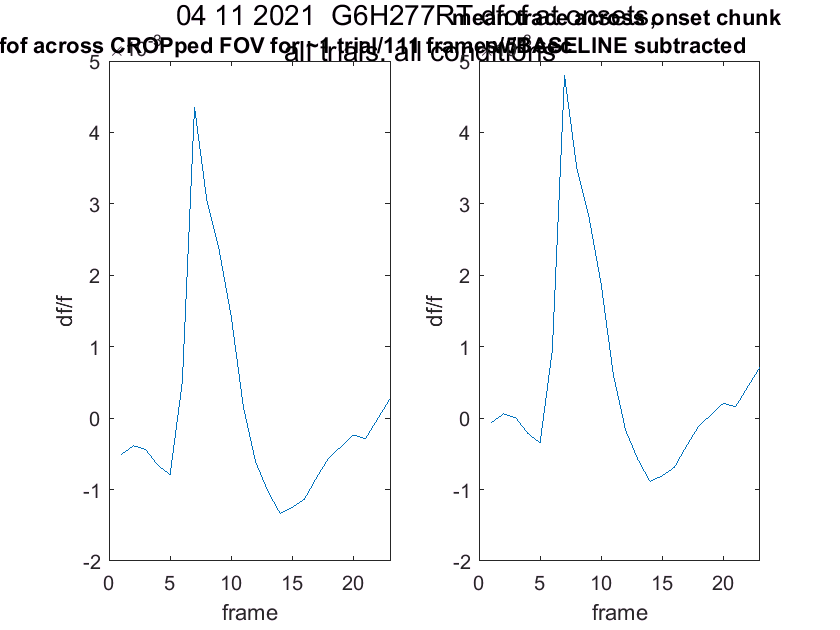

%% looking at the average trace over time for onsetFrame
% PRE & POST BASELINE

% mean across whole image, all trials/conditions
mnOnsetChunk = mean(squeeze(mean(squeeze(mean(onsetDf,1)))),2)';

numFrames = length(mnOnsetChunk);
numSec = (numFrames)*0.1;

figure

clear titleText
titleText = sprintf('dfof at onsets, \n all trials, all conditions');
suptitle(sprintf('%s ',date,subjName,titleText))

for j = 1:2 % pre & post baselined plots
    
    if j == 1
        
        % plot mean chunk trace
        subplot(1,2,j)
        plot(mnOnsetChunk)
        ylim([-0.002 0.005])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean dfof across CROPped FOV for ~1 trial/%0.00f frames/%0.00f sec',numFrames4title,numMins4title);
        title(sprintf('%s ',titleText))

    end 

    if j == 2  
        
        % index into just the baseline frames of the mean chunk
        allBaseMnOnsetChunk = mnOnsetChunk(1,baselineIdx);
        % get mean for 1st 4 frames
        meanBaseOnsetChunk = mean(allBaseMnOnsetChunk,2);
        %subtract mean from each cell in mnChunkOnset vector
        baselinedMnOnsetChunk = mnOnsetChunk-meanBaseOnsetChunk;
        % plot
        clear x_axis
        x_axis = 1:length(baselinedMnOnsetChunk);
        subplot(1,2,j)
        plot(x_axis,baselinedMnOnsetChunk)
        ylim([-0.002 0.005])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean trace across onset chunk \n w/BASELINE subtracted');
        title(sprintf('%s ',titleText))
        
    end
    
end

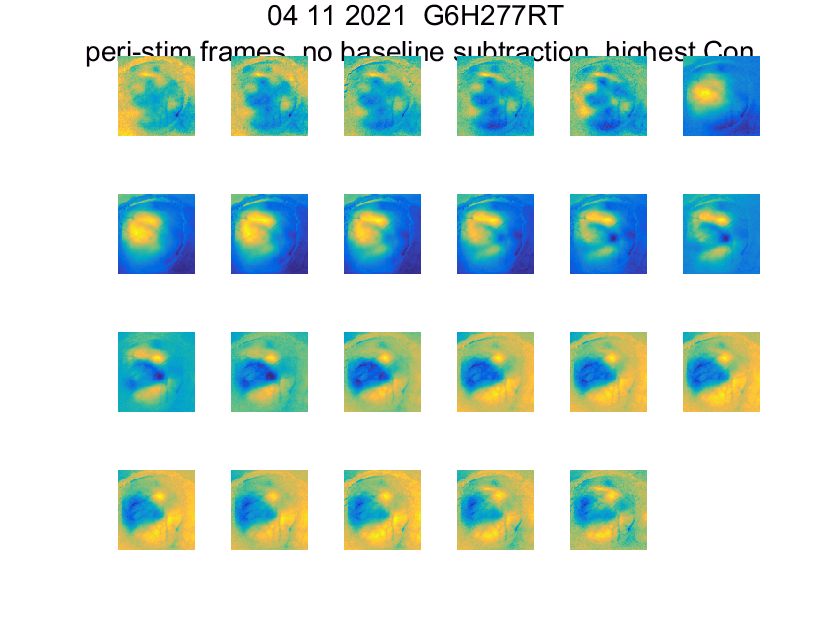

% PIXEL-WISE PERI-STIM (ONSETS), PRE BASELINE

% use FULL CONTRAST trials for example

% no baseline subtraction

clear seventhConTrials % use highest contrast, all durations
% conOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetFramesMeetBothCriteria);
seventhConTrials = conOrderedByTrial == uniqueContrasts(7);
 
clear frames
frames = 1:size(onsetDf,3);

clear range
range = 'not set';

clear frames4title
%frames4title = {'f 9';'f 10';'f 11';'f 12';'f 13';'f 14';'f 15';'f 16';'f 17';'f 18';};

figure

clear titleText
titleText = sprintf('\n peri-stim frames, no baseline subtraction, highest Con');
suptitle(sprintf('%s ',date,subjName,titleText))

clear f
for f = 1:length(frames)
        
     subplot(4,6,f)
    
     % show each frame
     imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4)); % ,range
     % st = title(sprintf('%s', frames4title{f}));
    
     axis off;
     axis image;
    
end


display('imagesc range is:')

imagesc range is:


range 

range = not set

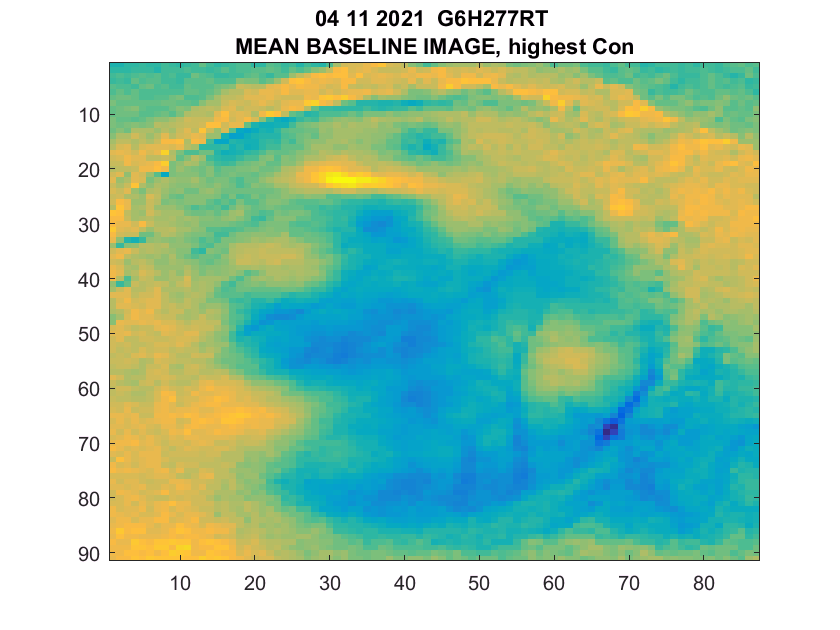

% CALCULATE MEAN BASELINE IMAGE
% need to subtract a mean baseline image
% get baseline frames, across all points, all trials/stimulus conditions
clear allBaselineFrameOnsetDf
allBaselineFrameOnsetDf = onsetDf(:,:,baselineIdx,:);

% now we can get selective

% get highest contrast trials only
clear seventhBaselineFrameOnsetDf
seventhBaselineFrameOnsetDf = allBaselineFrameOnsetDf(:,:,:,seventhConTrials);
% average over frames
clear meanBaselineImage
meanBaselineImage = mean(seventhBaselineFrameOnsetDf,3); % 3rd dim is frames
meanBaselineImage = squeeze(meanBaselineImage);
% average over trials
clear meanBaselineImage7thTrials
meanBaselineImage7thTrials = mean(meanBaselineImage,3); % this is the 
% "mean baseline image"

% SHOW MEAN BASELINE IMAGE
figure
clear range
range = [-0.008 0.005];
imagesc(meanBaselineImage7thTrials) % ,range
clear titleText
titleText = sprintf('\n MEAN BASELINE IMAGE, highest Con');
title(sprintf('%s ',date,subjName,titleText))


display('imagesc range is:')

imagesc range is:


range 

range =        -0.008        0.005


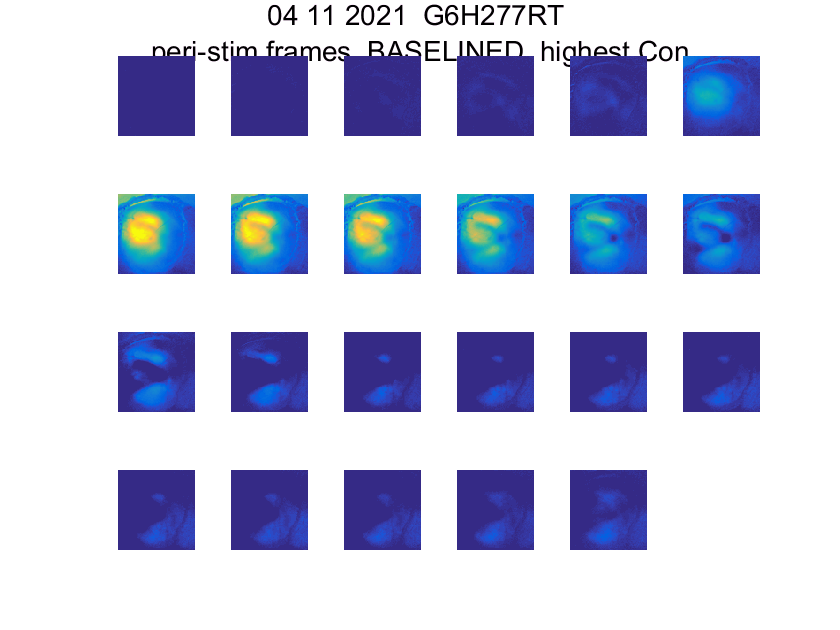

% plot all frames with mean baseline subtracted

clear seventhConTrials
seventhConTrials = conOrderedByTrial == uniqueContrasts(7);

clear range
range = [0 0.04];

figure
suptitle('peri-stim frames, w/baseline subtraction')
clear titleText
titleText = sprintf('\n peri-stim frames, BASELINED, highest Con');
suptitle(sprintf('%s ',date,subjName,titleText))

clear frames
frames = 1:size(onsetDf,3); % for every frame, subtract the baseline frame

for f = 1:length(frames)
    
    subplot(4,6,f)
  
    imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4)-meanBaselineImage7thTrials,range) %,range
    
    axis off;
    axis image;

end


display('imagesc range is:')

imagesc range is:


range 

range =             0         0.04


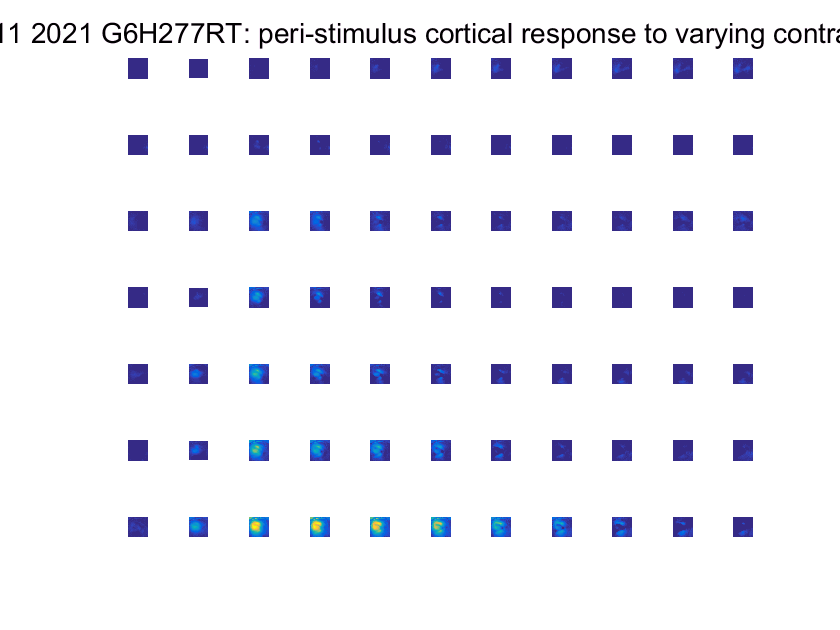

% PIXEL-WISE by CONTRAST minus BASEline

clear range
range = [0 0.04];

% which frames to plot over? peri-stim range
clear periStimFrameRange
periStimFrameRange = [stimOnsetFrame:1:stimOnsetFrame+10];

figure

clear titleText
titleText = ': peri-stimulus cortical response to varying contrasts'; % making char variables for sprintf/title later
supTit = suptitle(sprintf('%s', date, subjName, titleText));
%set(supTit, 'FontSize', 14)

clear c
for c = 1:length(uniqueContrasts);    

     clear cthTrials
     cthTrials = conOrderedByTrial == uniqueContrasts(c);
     
     % whole peri stim frame range, mean across trials
     periStimOnsetDf = mean(onsetDf(:,:,periStimFrameRange,cthTrials),4);
         
     % BASEline trials & mean
     baselinePeriStimOnsetDf = mean(onsetDf(:,:,baselineIdx,cthTrials),4); % baseline frames, mean across cth trials
     baselinePeriStimOnsetDf = squeeze(baselinePeriStimOnsetDf); 
     meanBaselinePeriStimOnsetDf = mean(baselinePeriStimOnsetDf,3); % mean across baseline frames & cth trials
     
     clear f
     for f = 1:length(periStimFrameRange)
         
         % baseline correction, one frame at a time
         eachBaselinedPeriStimOnsetDf = periStimOnsetDf(:,:,f)-meanBaselinePeriStimOnsetDf;
         allBaselinedPeriStimOnsetDf(:,:,f) = eachBaselinedPeriStimOnsetDf; % the whole frame range, baselined
         
         % plot, one frame at a time
         % BUT we need to change the frame/subplot index eaxh row/contrast

         newF = c-1; % gonna mult f by 0 if c = 1, 1 if f = 2
         newF = newF*length(periStimFrameRange); % always mult by nim frames in periStimFrameRange. So if 10 frames it's (c-1)*10, so newF = 0 if c=1, 10 if c = 2, 20 if c = 3... 60 if c = 7
         newF = f+newF; % finally, add f to get the new f index
         subplot(length(uniqueContrasts),length(periStimFrameRange),newF) 
         imagesc(allBaselinedPeriStimOnsetDf(:,:,f),range)

         axis off;
         axis image;
         
         hold on % keep plotting each new frame on same fig

     end % end f loop
    
end % end c loop


display('imagesc range is:')

imagesc range is:


range 

range =             0         0.04


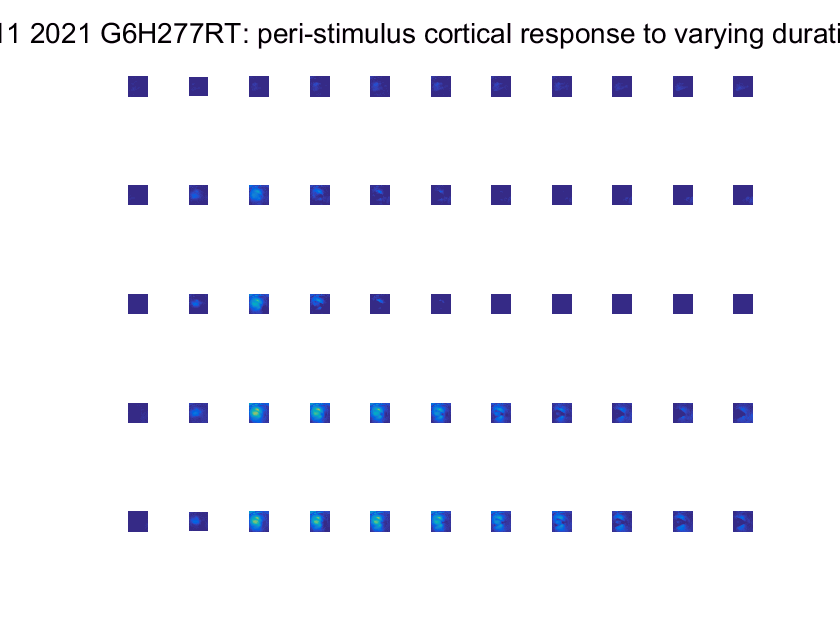

% PIXEL-WISE by DURATION minus BASEline

clear range
range = [0 0.04];

% which frames to plot over? peri-stim range
clear periStimFrameRange
periStimFrameRange = [stimOnsetFrame:1:stimOnsetFrame+10];

figure

clear titleText
titleText = ': peri-stimulus cortical response to varying durations'; % making char variables for sprintf/title later
supTit = suptitle(sprintf('%s', date, subjName, titleText));
%set(supTit, 'FontSize', 14)

clear d
for d = 1:length(uniqueDurations);    

     clear dthTrials
     dthTrials = durOrderedByTrial == uniqueDurations(d);
     
     % whole peri stim frame range, mean across trials
     periStimOnsetDf = mean(onsetDf(:,:,periStimFrameRange,dthTrials),4);
         
     % BASEline trials & mean
     baselinePeriStimOnsetDf = mean(onsetDf(:,:,baselineIdx,dthTrials),4); % baseline frames, mean across cth trials
     baselinePeriStimOnsetDf = squeeze(baselinePeriStimOnsetDf); 
     meanBaselinePeriStimOnsetDf = mean(baselinePeriStimOnsetDf,3); % mean across baseline frames & cth trials
     
     clear f
     for f = 1:length(periStimFrameRange)
         
         % baseline correction, one frame at a time
         eachBaselinedPeriStimOnsetDf = periStimOnsetDf(:,:,f)-meanBaselinePeriStimOnsetDf;
         allBaselinedPeriStimOnsetDf(:,:,f) = eachBaselinedPeriStimOnsetDf; % the whole frame range, baselined
         
         % plot, one frame at a time
         % BUT we need to change the frame/subplot index eaxh row/contrast
         clear newF
         newF = d-1; % gonna mult f by 0 if d = 1, 1 if d = 2...
         newF = newF*length(periStimFrameRange); % then mult by num frames in periStimFrameRange. So if 10 frames it's (c-1)*10, so newF = 0 if c=1, 10 if c = 2, 20 if c = 3... 60 if c = 7
         newF = f+newF; % finally, add f to get the new f index
         subplot(length(uniqueDurations),length(periStimFrameRange),newF) 
         imagesc(allBaselinedPeriStimOnsetDf(:,:,f),range)

         axis off;
         axis image;
         
         hold on % keep plotting each new frame on same fig

     end % end f loop
    
end % end c loop


display('imagesc range is:')

imagesc range is:


range 

range =             0         0.04


% PIXEL-WISE ALL STIM CONDITIONS
% I want to plot one big image matrix of all stim conditions... 
% I think I'll have to pick just one time point for that
% take the mean of peak frames for that "one time point"


% get PEAK FRAMES

clear peakFrameIdx
clear f
for f = 1:3 % average over 3 peak frames
   peakFrameIdx(f) = stimOnsetFrame+1+f; % always skip the onset frame and the one after, then take the
   % next 3 frames
end % now you can index the peak frames automatically if you change stim onset
display('peak frame indicies are:')

peak frame indicies are:


peakFrameIdx

peakFrameIdx =      7     8     9


% SHOW IMAGES for each STIM COND at PEAK response

clear range
range = [0 0.07];

clear subplotNum
subplotNum = 1;

clear fig
fig = figure % one fig all images % need fig var to alter axes later

fig =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [472.33 479.67 560 420]
       Units: 'pixels'

  Show all properties


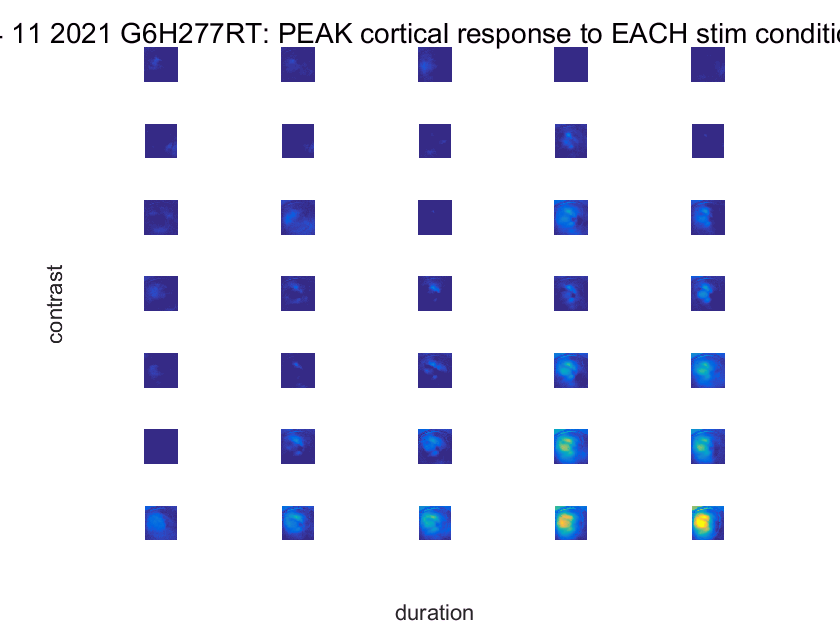


clear titleText
titleText = ': PEAK cortical response to EACH stim condition'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

% index into trials for each combo of DUR & CON @ peak frames

 % for each contrast (row):
 for c = 1:length(uniqueContrasts)
            
    % going to plot the contrast (row) at each duration (column)
    for d = 1:length(uniqueDurations)
        
        clear cthDthPeakImage
             
        clear cthDthTrials 
        cthDthTrials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrial(2,:) == uniqueDurations(d);
             
         %numTrials = sum(cthDthTrials);
         %display('num cthDth trials = ')
         
         % get MEAN PEAK IMAGE across CTHDTH TRIALS
         allPeakFramesCthDthtrialsOnsetDf = onsetDf(:,:,peakFrameIdx,cthDthTrials);
         mnPeakFramesCthDthtrialsOnsetDf = mean(allPeakFramesCthDthtrialsOnsetDf,3);
         mnPeakFramesCthDthtrialsOnsetDf = squeeze(mnPeakFramesCthDthtrialsOnsetDf); % mean over peak frames
         mnPeakFramesMnCthDthtrialsOnsetDf = mean(mnPeakFramesCthDthtrialsOnsetDf,3); % mean over trials
         meanPeakImageCthDthTrials = squeeze(mnPeakFramesMnCthDthtrialsOnsetDf);
         
         % get BASEline IMAGE at cthdth trials
         allBaseFramesCthDthtrials = onsetDf(:,:,baselineIdx,cthDthTrials);
         meanBaseFramesCthDthtrials = mean(allBaseFramesCthDthtrials,3); % mean over frames
         meanBaseFramesCthDthtrials = squeeze(meanBaseFramesCthDthtrials);
         meanBaseFramesCthDthtrials = mean(meanBaseFramesCthDthtrials,3);
         meanBaseImageCthDthtrials = squeeze(meanBaseFramesCthDthtrials);
         
         % subtract baseline from mean peak image
         % just subtracting an image from an image here, not subtracting one baseline value from each cell in a trace
         baselinedPeakImageCthDthTrials =  meanPeakImageCthDthTrials-meanBaseImageCthDthtrials;
         
         % PLOT BASElined PEAK image
         subplot(length(uniqueContrasts),length(uniqueDurations),subplotNum)
         imagesc(baselinedPeakImageCthDthTrials,range)
         
         axis off;
         axis image;
         
         subplotNum = subplotNum+1; % use this to index subolots because it 
         % increases by every time a stim cond is plotted
         
         hold on % plotting all stim conditions on same fig, diff subplots (subplotNum)
         
    end % end d loop
    
 end % end c loop   
 
 % Give common xlabel & ylabel
han=axes(fig,'visible','off'); 
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'contrast');
xlabel(han,'duration');

             
display('imagesc range is:')

imagesc range is:


range              

range =             0         0.07


% PICK PTS for REIGON-specific analyses


% now we need outputs from do_topo_KC

% choose FILE(S)
warning off
batchNEW_KC;

pathname = F:\Kristen\Widefield2\

datapathname = F:\Kristen\Widefield2\

outpathname = F:\Kristen\Widefield2\

files =              subj: 'G6H277RT'
             expt: '041121'
            topox: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_TOPOX\041121_G6H277RT_RIG2_TOPOXmaps.mat'
        topoxdata: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_TOPOX\041121_G6H277RT_RIG2_TOPOX'
            topoy: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_TOPOY\041121_G6H277RT_RIG2_TOPOYmaps.mat'
        topoydata: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_TOPOY\041121_G6H277RT_RIG2_TOPOY'
           thresh: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_THRESH\041121_G6H277RT_RIG2_THRESH'
       threshdata: '041121_G6H277RT_RIG2\041121_G6H277RT_RIG2_THRESH\041121_G6H277RT_RIG2_THRESH'
           inject: 'none'
             dose: 'none'
            virus: 'none'
           timing: 'none'
         training: 'naive'
             area: 'none'
           rignum: 'rig2'
          monitor: 'land'
         genotype: 'camk2 gc6'
        imagerate: 10
    moviename4x3y: 'none'


f =      1


f =      1


aligning


f =      1


computing averages


f =      1


ans =      0


ans =      0


avgmapfig =   Figure (42) with properties:

      Number: 42
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [572.33 558.33 360 263.33]
       Units: 'pixels'

  Show all properties


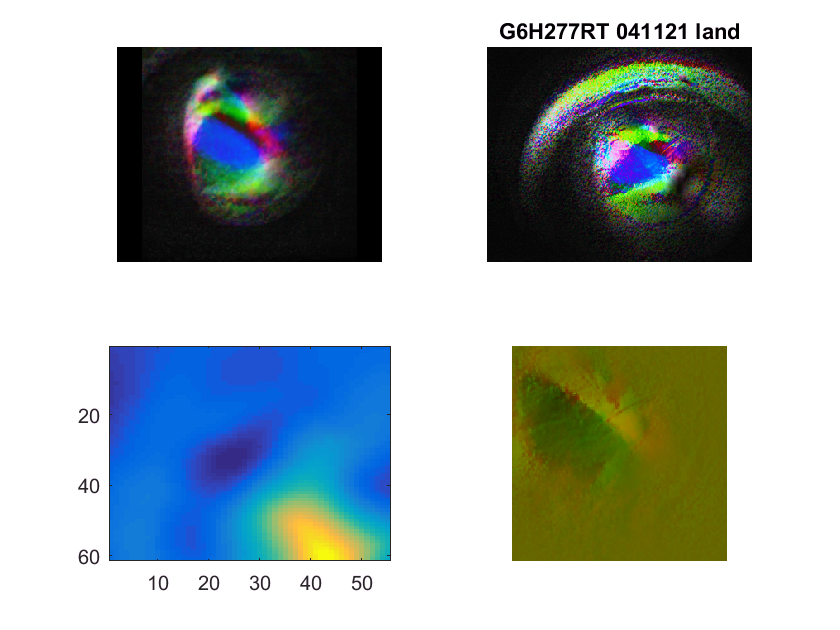

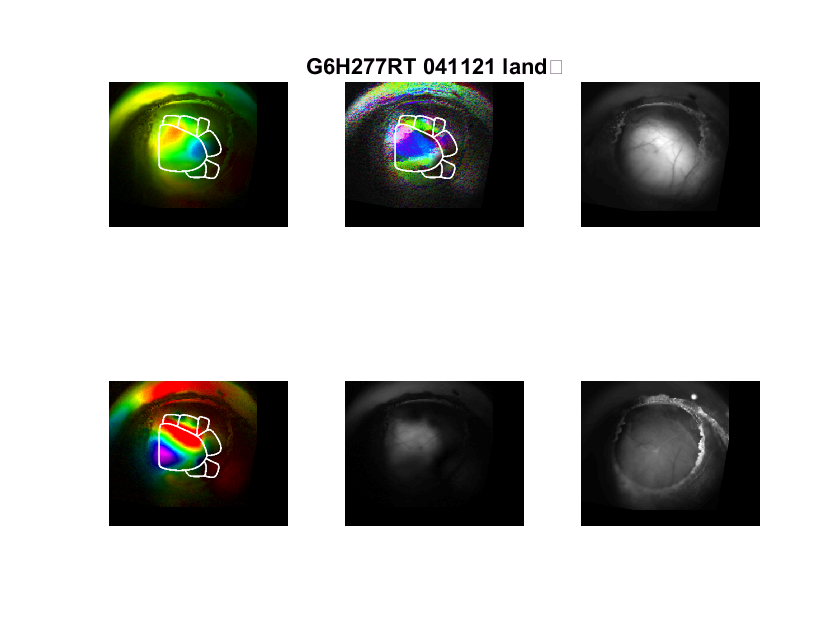

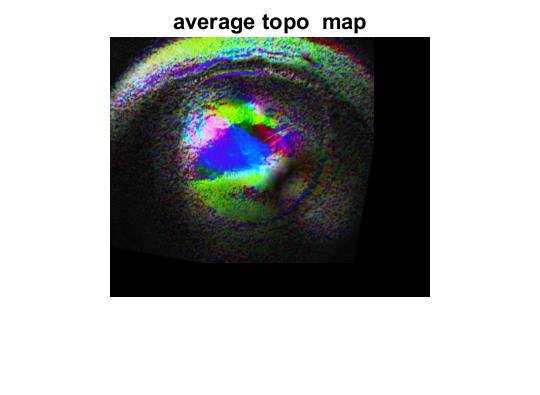

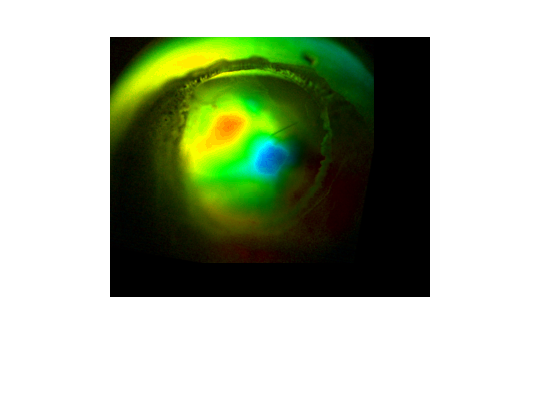

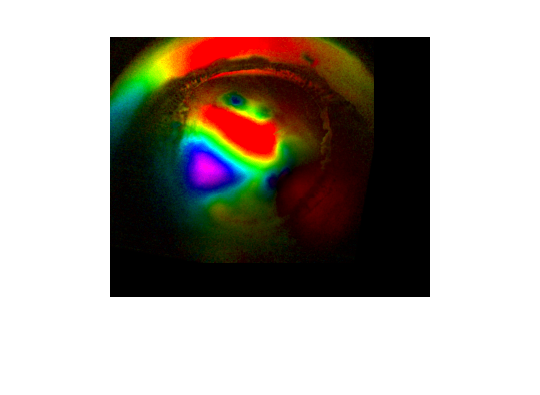

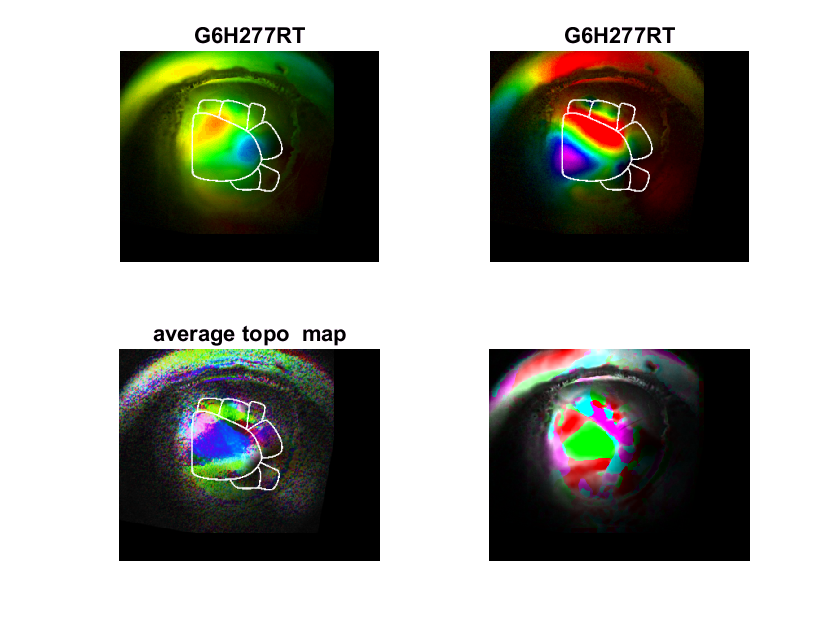

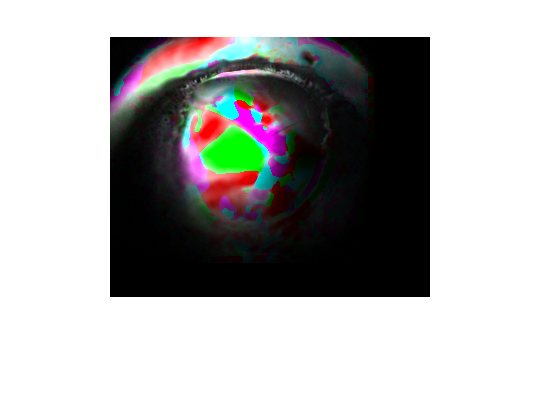

cd(pathname);

%% select the fields that you want to filter on
alluse = find(strcmp({files.subj},'G6H277RT')...
      & strcmp({files.expt},'041121'));
  
% temp file needs to exist for some reason
psfilename = fullfile(pathname,'tempWF.ps'); 
if exist(psfilename,'file')==2
    delete(psfilename)
end   
  
% run doTopography on map file info (df/f) from dfOfMovie
allsubj = unique({files(alluse).subj});

for s = 1:1
    
    use = alluse;

    % calculate gradients and regions
    clear map merge
    x0=0; y0=0; sz=128;
    doTopography;
    
end

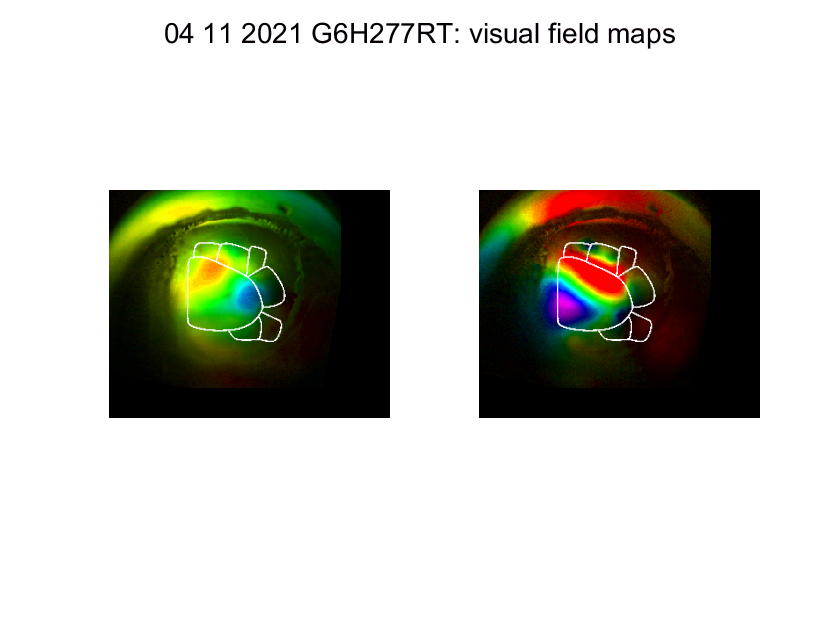

% VIEW topox & y w/overlay first, before picking
% points on activation image

% vars xpts & ypts are from doTopography

figure

clear titleText
titleText = ': visual field maps'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for m=1:2
    subplot(1,2,m);
    
    imshow(polarMap(meanpolar{m},95))
    
    hold on
    
    plot(ypts,xpts,'w.','Markersize',2)
    
end

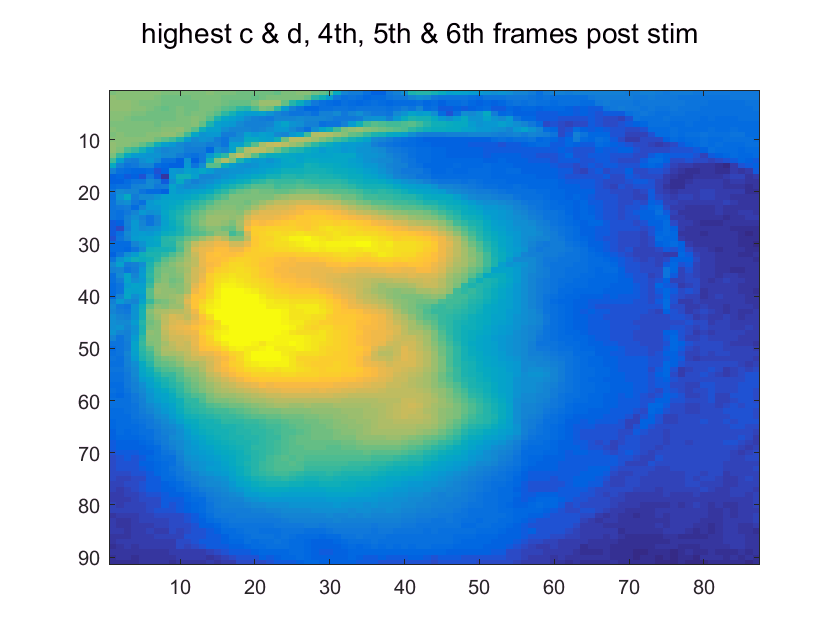

% PICKING ACTIVATION IMAGE - *needs onsetDf*

% image of highest contrast & duration during peak response

clear c7d5trials
c7d5trials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(7) & conAndDurOrderedByTrial(2,:) == uniqueDurations(5);

% within the chunk of frames in onsetDf, which do you want indexed/averaged over?
% always pick the 4th, 5th, & 6th frames following stim onset, b/c that shows
% "imprint" of vis ctx best
clear actImIdx
actImIdx = [stimOnsetFrame+4, stimOnsetFrame+5, stimOnsetFrame+6]; % stimOnsetFrame defined in making onsetDf code

% get selected frames from onsetDf 
clear allActImFrames
clear f

% get all act im frames at highest c & d
clear allActImFrames
allActImFrames = onsetDf(:,:,actImIdx,c7d5trials); 
% take the average of the image across frames
clear meanActImFrames
meanActImFrames = squeeze(mean(allActImFrames,3));
meanActImFrames = mean(meanActImFrames,3);

% plot the mean peak activation image at highest stim parameters
figure
suptitle('highest c & d, 4th, 5th & 6th frames post stim')
range = [0 0.073]; 
imagesc(meanActImFrames,range)


display('imagesc range is:')

imagesc range is:


range 

range =             0        0.073


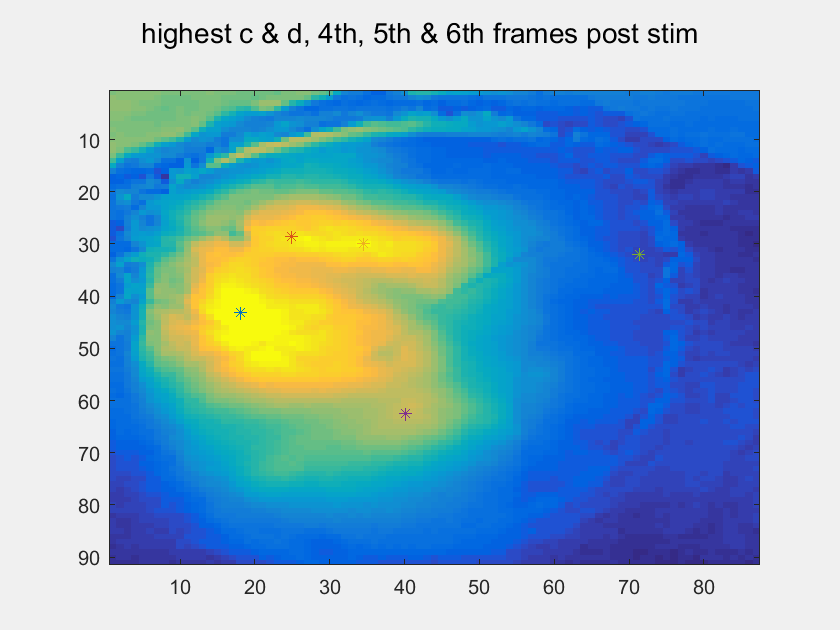

% pick 5 pts - V1, motor ctx, 3 HVAs

clear xPickedPts 
clear yPickedPts 

% show activation image
figure
suptitle('highest c & d, 4th, 5th & 6th frames post stim')
range = [0 0.073]; 
imagesc(meanActImFrames,range)
 
for i = 1:5
   
    hold on
    [xPickedPts(i) yPickedPts(i)] = ginput(1);
    plot(xPickedPts(i),yPickedPts(i),'*');
   
end

% SELECT PTS from ONSET DF

RoundXpts = round(abs(yPickedPts)); %switch x & y
RoundYpts = round(abs(xPickedPts));

clear PTSdfof 
for i = 1:length(xPickedPts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')

size of PTSdfof is: 


size(PTSdfof)

ans =            5          23        1343


% COMPARing PRE & POST BASELINE analyses for V1


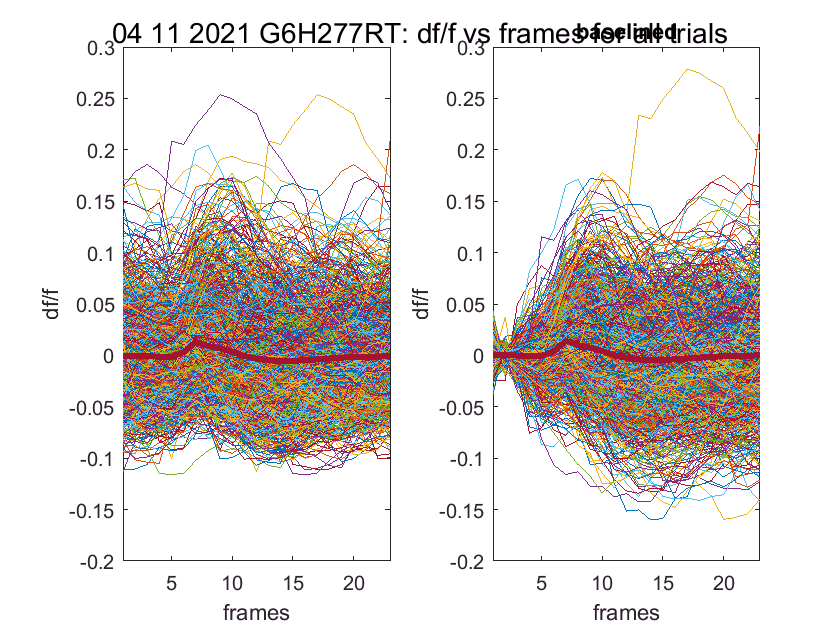

% V1, PRE & POST BASEline

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for j = 1:2 % pre & post baseline figs

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot

        clear recomboOnePtAllFramesAllTrialMinusMeanBase
        clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
        % collect all trials over all frames for the ith point
        clear onePtAllFramesAndTrials % new var each point
        onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
        onePtAllFramesAndTrials = onePtAllFramesAndTrials';
        
         if j == 1 % if making pre-baselined fig
                
           % pre baseline fig
           subplot(1,2,j)
                
           clear x_axis
           x_axis = 1:size(onePtAllFramesAndTrials,2); % length of frames
           % plot one baseline corrected trace at a time
           %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
           % hold on because we're doing it for every trial on the same plot
           plot(x_axis,onePtAllFramesAndTrials)
               
           hold on
           % plot each mean trace
           clear meanOnePtAllFramesAndTrials
           meanOnePtAllFramesAndTrials = mean(onePtAllFramesAndTrials,1); % mean across trials
           % plot mean non-baselined
           plot(x_axis,meanOnePtAllFramesAndTrials,'linewidth',3)
           title('V1')
            
           ylim([-0.2 0.3]) 
           xlim([1 length(x_axis)])
           ylabel('df/f')
           xlabel('frames')
    
           ax = gca;
           x.XTick = [1:1:length(x_axis)];
                
       end 
       
       if j == 2; % if making baseline fig
            
       % for every trace, subtract the baseline value at that point from each frame value
  
           clear tr % for each trial in onePtAllFramesAndTrial
           for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
              % getting TRIAL VECTOR
              clear onePtAllFramesOneTrial % make new var for each trial
              % index into each trace/vector & save as variable
              onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
        
              % getting MEAN BASEline VALUE for each TRIAL
              clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
              % collect 4 baseline frames for tr-th ith trial
              allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
              clear mean4baseFramesOnePtOneTrial
              % get mean value of baseline values for ith point
              mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
              mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
              % BASEline CORRECTion of TRIAL VECTOR
        
              % new baseline-corrected trace for each trial
              % calulate the baselined trace for the ith trial
              onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
              % collect CORRECTed TRIAL VECTORS in matrix
              % save each tr-th baselined trace in a matrix for plotting mean later
              % (only clear this outside the loop for each point)
              recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
             % PLOT
             subplot(1,2,j) % post baseline fig
             clear x_axis
             x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
             % plot one baseline corrected trace at a time
             %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
             % hold on because we're doing it for every trial on the same plot
             plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
             hold on % hold for next trial
                
         end % end tr loop
        
      % outside of trial loop but inside j 'if'
      
      hold on % hold for plotting mean over subplot
        
      % get mean baselined trace across all trials
      meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
      plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
      title('baselined')
        
      ylim([-0.2 0.3]) 
      xlim([1 length(x_axis)])
      ylabel('df/f')
      xlabel('frames')

      ax = gca;
      x.XTick = [1:1:length(x_axis)];
                
       end % end 2nd if statement
       
    end % end i loop
    
end % end j loop

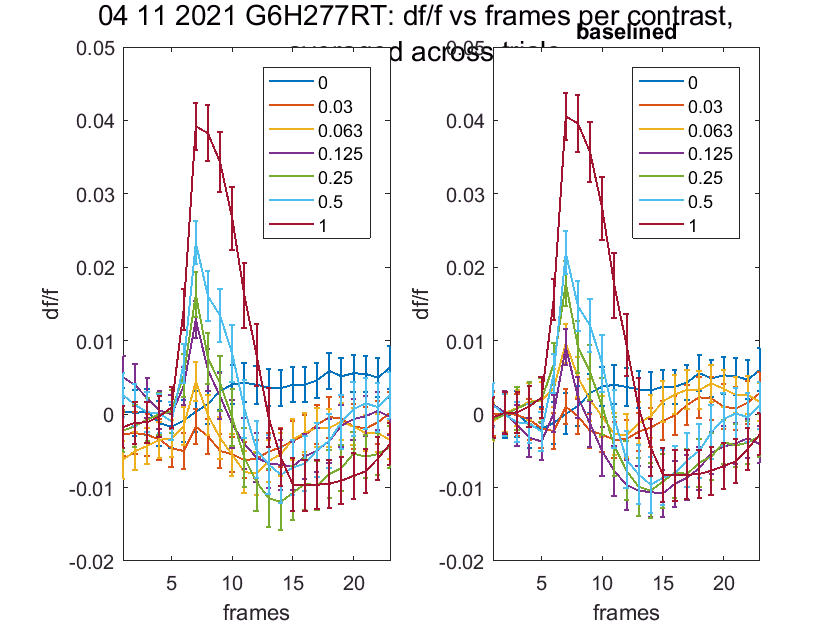

% V1, PRE & POST BASEline

% MEAN across TRIALS for each CONTRAST

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per contrast, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));


for j = 1:2 % pre & post baseline figs
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % MEAN over trials
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x51 variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frames
            
                %STDEV
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
                % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
            
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(meanOverTrialsPTSdfof);
                subplot(1,2,j)
                errorbar(x_axis,meanOverTrialsPTSdfof,err,'linewidth',1)
                
                title('V1')
                ylim([-0.02 0.05]) 
                xlim([1 length(x_axis)])
                %st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
            
            hold on
            legend(cons4Legend)
       
        end % end 1st j if
           
        if j == 2; % if making baseline fig
           
           subplot(1,2,j)
           
           clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % MEAN over trials
                clear meanOverTrialsPTSdfof
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x # trials variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frame
                
                % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
                % trials and we already took the mean across trials
                clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
                % collect 4 baseline frames 
                allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
                clear mean4baseFramesOnePtOneCon
                % get mean value of baseline values for ith point
                mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
                % BASEline CORRECTION
                % new baseline-corrected trace for each mean trace
                clear onePtOneConMinusMeanBase
                onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
                % COLLECT corrected traces in matrix
                % (only clear this each tine go thru j loop (new one each subplot)
                recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
                %STDEV of deviation from the mean oover trials
                clear err
                % our mean trace is averaged over trials. We want to know how much the trials 
                % values varied, not how much the mean trial values vary over time...
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(onePtOneConMinusMeanBase);
                subplot(1,2,j)
                errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
                ylim([-0.02 0.05])  
                xlim([1 length(x_axis)])
                title('baselined')
                % st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
            
            hold on
            legend(cons4Legend)
                
       end % end 2nd j if
       
    end % end i loop
    
end % end j loop

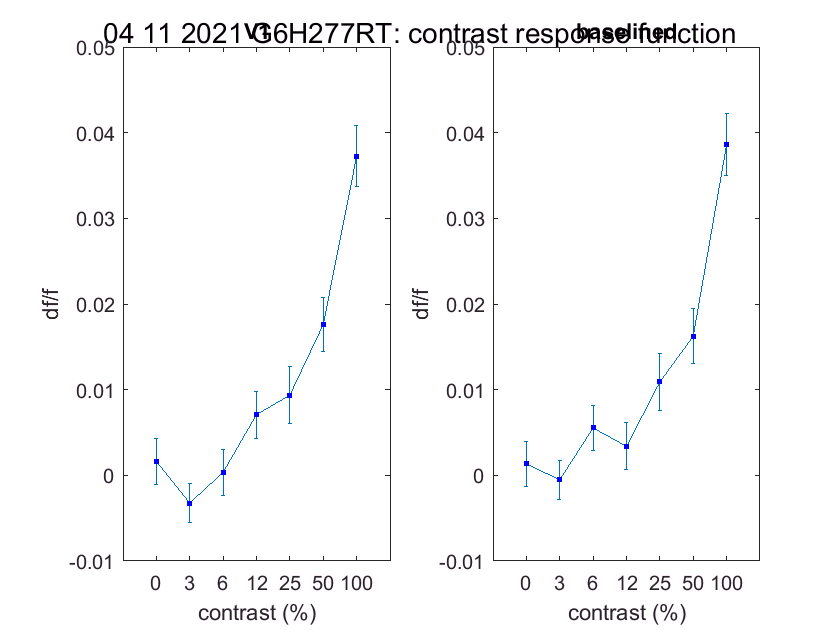

% V1, PRE & POST BASEline
% CRF
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': contrast response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for j = 1:2 % pre & post baseline figs
    
    clear contStdErr
    clear crf
    clear CRFminusMeanBase

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) % get mean peak response for each contrast (CRF)
                
                % TRIALS
                clear cthTrials
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
      
                % calculate CRF
                % take the i-th points over the peak frame range, for the c-th trials
                % returns 3 (frames) by # trials
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
                % take the mean over frames
                %returns 1 x # trials
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now I need the mean over trials to get one df/f value (CRF value) representing the
                % average fluorescence over peak frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
                % now I want to collect each c-th CRF value for this point
                % creates 1 x 7 (contrasts)
                crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear this outside j loop
        
            end % end contrast loop - have full CRF for ith point
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = [1 2 3 4 5 6 7];
            crfChart = errorbar(x_axis,crf,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
        
            title('V1')
            %st = title(sprintf('%s', reigons{i}));
            ylim([-0.01 0.05]) 
            xlim([0, 8])
    
%             ax=crfChart.Parent;
%             ax.XMinorTick = 'on'; %more tick marks
%             set(ax, 'XTick', 0:1:8);

            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            set(gca,'xtick',1:7); 
            set(gca,'xticklabel',xt);
    
             ylabel('df/f')
             xlabel('contrast (%)')
                
        end % end 1st if statemet
             
        if j == 2; % if making baseline fig
               
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % calculate CRF
                % take the i-th points over the frame range, for the c-th trials
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
                % take the mean over frames, returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now I need the mean over trials to get one df/f value representing the
                % average fluorescence over 3 frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
                % collect each c-th CRF value for this point
                crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for
                % the ith point and cth contrast
                % get all frames & cth trials
                clear baselineFramesIthPtCthTrials
                baselineFramesIthPtCthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
                % now have baseline frames x trials
                % take mean across trials 
                clear  meanBaselineFramesIthPtCthTrial
                meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
                %meanBaselineFramesIthPtCthTrials = squeeze(baselineFramesIthPtCthTrials);
                % take mean across frames
                meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots

                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear outside j loop
        
            end % end contrast loop - have full baselined CRF for ith point
            
            % inside 2nd j loop still
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = [1 2 3 4 5 6 7];
            crfChart = errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
            %st = title(sprintf('%s', reigons{i}));
            ylim([-0.01 0.05]) 
            xlim([0, 8])
            title('baselined')
    
%             ax=crfChart.Parent;
%             ax.XMinorTick = 'on'; %more tick marks
%             set(ax, 'XTick', 0:1:8);
                
            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            set(gca,'xtick',1:7); 
            set(gca,'xticklabel',xt);
    
             ylabel('df/f')
             xlabel('contrast (%)')
     
        end % end 2nd j if statement
            
    end % end i loop
    
end % end j loop

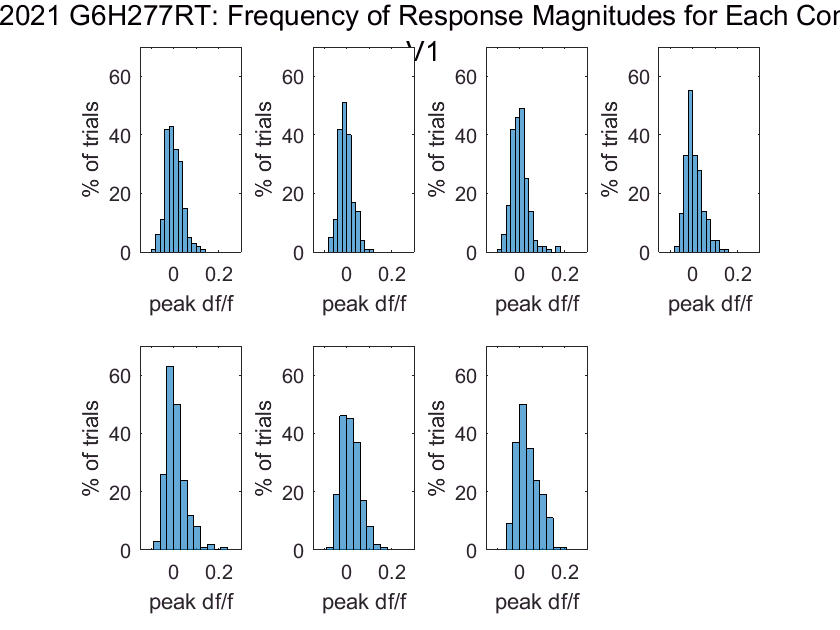

% DISTRIBUTION by CONTRAST - 2 figs, PRE *NO* BASEline

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for Each Contrast, \n V1'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 1 % for V1
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the cth trials
        clear cthTrials
        cthTrials = conOrderedByTrial == uniqueContrasts(c);
        % take df/f data for ith pt, peak frames, cth trials
        allPeakFramesCthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthTrials)); 
        meanPeakFramesCthTrialsIthPt = mean(allPeakFramesCthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        %numBins = sum(cthTrials);
        histogram(meanPeakFramesCthTrialsIthPt)
        xlabel('peak df/f')
        ylabel('% of trials')
        ylim([0 70])
        xlim([-0.15 0.3])
        
        hold on  
        
    end
       
end

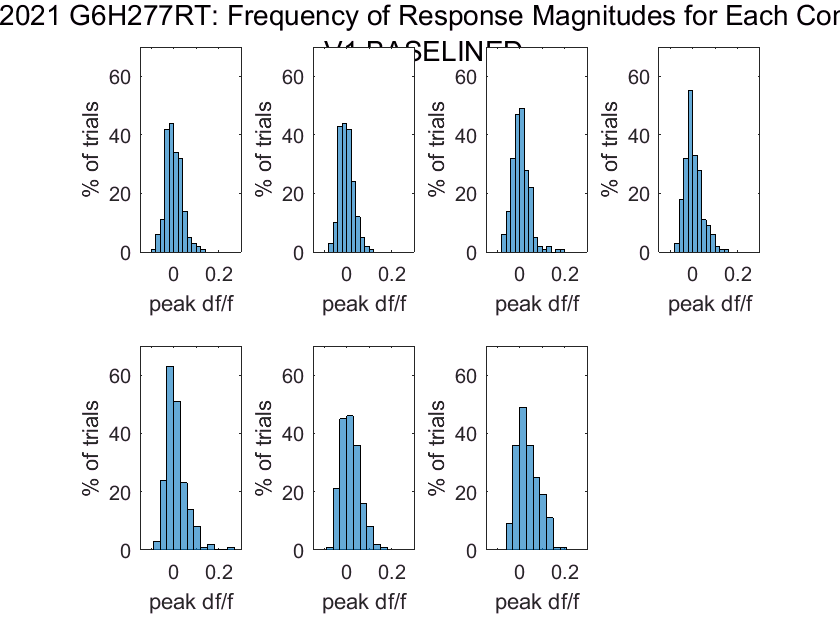

% DISTRIBUTION by CONTRAST - 2 figs, PRE *YES* BASEline

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for Each Contrast, \n V1 BASELINED'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 1 % for V1
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the CTH TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrial == uniqueContrasts(c);
        % take df/f data for ith pt, peak frames, cth trials
        allPeakFramesCthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthTrials)); 
        meanPeakFramesCthTrialsIthPt = mean(allPeakFramesCthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthTrialsIthPtMinusBase = meanPeakFramesCthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        %numBins = sum(cthTrials);
        histogram(meanPeakFramesCthTrialsIthPtMinusBase)
        xlabel('peak df/f')
        ylabel('% of trials')
        ylim([0 70])
        xlim([-0.15 0.3])
        
        hold on  
        
    end
       
end